# Operating point




V_vsc_mag=0.98;P_t=P_aero_0;x_sys=0.8768

x_sys = 0.8768

delta_vsc_0=asin((x_sys*P_t/V_vsc_mag))

delta_vsc_0 = 0.5667

delta_vsc_0*180/pi

ans = 32.4672

V_vsc=V_vsc_mag*(cos(delta_vsc_0)+1i*sin(delta_vsc_0))

V_vsc = 0.8268 + 0.5261i

Q_t=(V_vsc_mag^2-cos(delta_vsc_0))/x_sys

Q_t = 0.1331

I_vsc=conj((P_t+1i*Q_t))/(V_vsc_mag*(cos(delta_vsc_0)-1i*sin(delta_vsc_0)))

I_vsc = 0.5895 + 0.2141i

angle(I_vsc);ans*180/pi

ans = 19.9597

abs(I_vsc)

ans = 0.6271

V_t=V_vsc_mag*(cos(delta_vsc_0)+1i*sin(delta_vsc_0))+1i*I_vsc

V_t = 0.6127 + 1.1155i

delta_t=angle(V_t); delta_t*180/pi

ans = 61.2206

V_t_mag=abs(V_t)

V_t_mag = 1.2727



v_D0_vsc =real(V_vsc), v_Q0_vsc = imag(V_vsc)

v_D0_vsc = 0.8268

v_Q0_vsc = 0.5261

i_D0_vsc = real(I_vsc), i_Q0_vsc = imag(I_vsc)

i_D0_vsc = 0.5895

i_Q0_vsc = 0.2141

v_d0_t = real(V_t), v_q0_t = imag(V_t)

v_d0_t = 0.6127

v_q0_t = 1.1155

theta_0_vsc = 0.8354107558;



% dq/DqQ transformation matrices
P_meas = [v_D0_vsc v_Q0_vsc i_D0_vsc i_Q0_vsc]

P_meas =     0.8268    0.5261    0.5895    0.2141


Q_meas = [v_Q0_vsc -v_D0_vsc -i_Q0_vsc i_D0_vsc]

Q_meas =     0.5261   -0.8268   -0.2141    0.5895


v_D_t = [-v_q0_t*sin(delta_vsc_0)+v_d0_t*cos(delta_vsc_0) cos(delta_vsc_0) sin(delta_vsc_0) ]

v_D_t =    -0.0819    0.8437    0.5368


v_Q_t = [-v_d0_t*cos(delta_vsc_0)-v_q0_t*sin(delta_vsc_0) -sin(delta_vsc_0) cos(delta_vsc_0) ]

v_Q_t =    -1.1158   -0.5368    0.8437


v_d_vsc = [-v_Q0_vsc*sin(delta_vsc_0)-v_D0_vsc*cos(delta_vsc_0) cos(delta_vsc_0) -sin(delta_vsc_0) ]

v_d_vsc =    -0.9800    0.8437   -0.5368


v_q_vsc = [v_D0_vsc*cos(delta_vsc_0)-v_Q0_vsc*sin(delta_vsc_0) sin(delta_vsc_0) cos(delta_vsc_0) ]

v_q_vsc =     0.4152    0.5368    0.8437


i_d_vsc = [-i_Q0_vsc*sin(delta_vsc_0)-i_D0_vsc*cos(delta_vsc_0) cos(delta_vsc_0) -sin(delta_vsc_0) ]

i_d_vsc =    -0.6122    0.8437   -0.5368


i_q_vsc = [i_D0_vsc*cos(delta_vsc_0)-i_Q0_vsc*sin(delta_vsc_0) sin(delta_vsc_0) cos(delta_vsc_0) ]

i_q_vsc =     0.3824    0.5368    0.8437



T_vdq_DQ = [v_D_t; v_Q_t]

T_vdq_DQ =    -0.0819    0.8437    0.5368
   -1.1158   -0.5368    0.8437


T_vDQ_dq = [v_d_vsc; v_q_vsc]

T_vDQ_dq =    -0.9800    0.8437   -0.5368
    0.4152    0.5368    0.8437


T_iDQ_dq = [i_d_vsc; i_q_vsc]

T_iDQ_dq =    -0.6122    0.8437   -0.5368
    0.3824    0.5368    0.8437



T_PQ_meas = [P_meas; Q_meas]

T_PQ_meas =     0.8268    0.5261    0.5895    0.2141
    0.5261   -0.8268   -0.2141    0.5895


## p/angle controller



k_d_vsm= 2500

k_d_vsm = 2500

% 
H_vsm = 2

H_vsm = 2

T_vsm = tf([omega_nom/(2*H_vsm*l_f/omega_nom)*cos(delta_vsc_0)],[1 k_d_vsm/(2*H_vsm) omega_nom/(2*H_vsm*l_f/omega_nom)*cos(delta_vsc_0)])

T_vsm =
 
         1.972e05
  ----------------------
  s^2 + 625 s + 1.972e05
 
Continuous-time transfer function.
Model Properties



G_vsm = omega_nom/(2*H_vsm*s+k_d_vsm)

G_vsm =
 
    314.2
  ----------
  4 s + 2500
 
Continuous-time transfer function.
Model Properties



zeta_vsm = k_d_vsm/H_vsm*sqrt(2*H_vsm*x_sys/omega_nom)

zeta_vsm = 132.0734

nf_vsm = sqrt(omega_nom/(2*H_vsm*x_sys))

nf_vsm = 9.4644

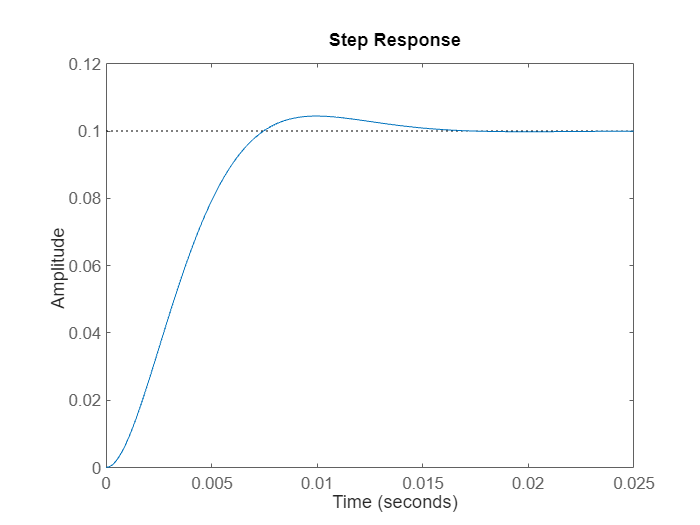

step(T_vsm*0.1)

## q controller droop


ki_q = 2*pi*10

ki_q = 62.8319

k_p_q_vsm = -0.05

k_p_q_vsm = -0.0500


% open loop

%closed loop 
T_q_vsm = tf([ki_q*k_p_q_vsm/x_sys],[1 ki_q+k_p_q_vsm*ki_q/x_sys])

T_q_vsm =
 
   -3.583
  ---------
  s + 59.25
 
Continuous-time transfer function.
Model Properties



%open loop Q_grid -> delta V_d_ref
G_qdroop = tf([ki_q*k_p_q_vsm],[1 ki_q])

G_qdroop =
 
   -3.142
  ---------
  s + 62.83
 
Continuous-time transfer function.
Model Properties


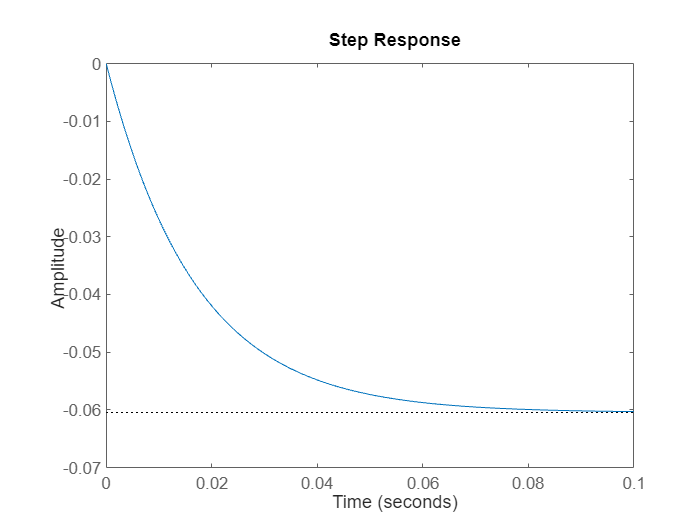


step(T_q_vsm)

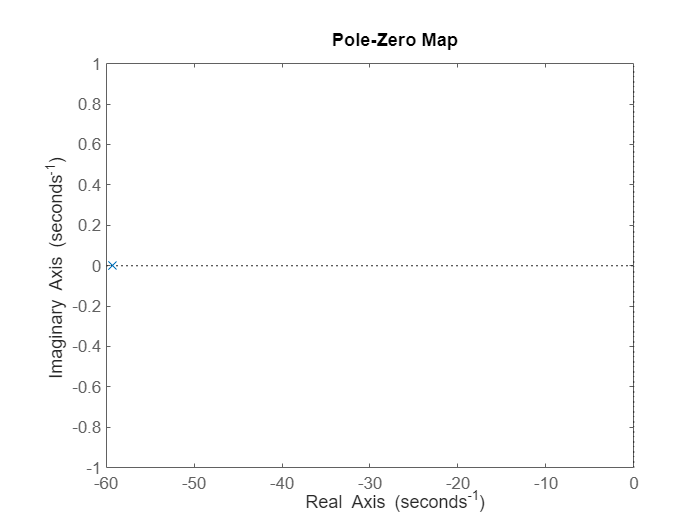

% step(T_e_vsm)

pzmap(T_q_vsm)

## current control

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


ti = 5/f_sw

ti = 0.0017

G_plant = 1/(s*l_f/omega_nom+r_f)

G_plant =
 
       314.2
  ----------------
  0.1056 s + 1.658
 
Continuous-time transfer function.
Model Properties


kp = (l_f/omega_nom)/ti

kp = 62.2908

ki = r_f/ti

ki = 3.1145

G_cc = (kp*s+ki)/s

G_cc =
 
  62.29 s + 3.115
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_cc = G_plant*G_cc/(1+G_plant*G_cc)

T_cc =
 
         2066 s^3 + 3.256e04 s^2 + 1623 s
  ----------------------------------------------
  0.01115 s^4 + 2066 s^3 + 3.256e04 s^2 + 1623 s
 
Continuous-time transfer function.
Model Properties



tf2ss([kp ki], [1 0])

ans = 0

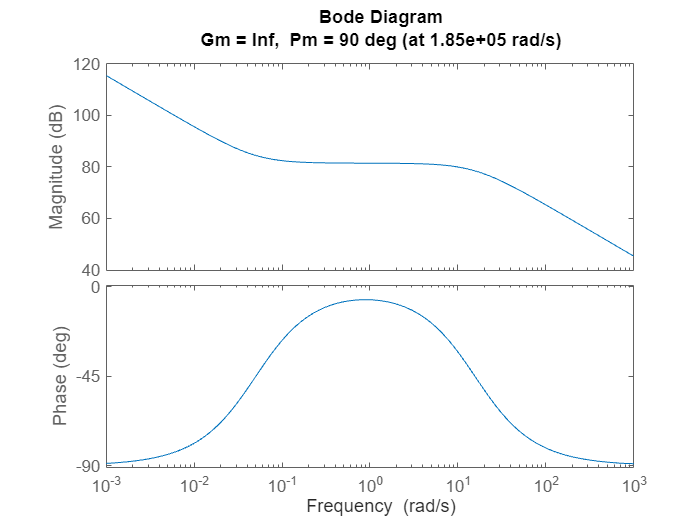

margin(G_plant*G_cc)

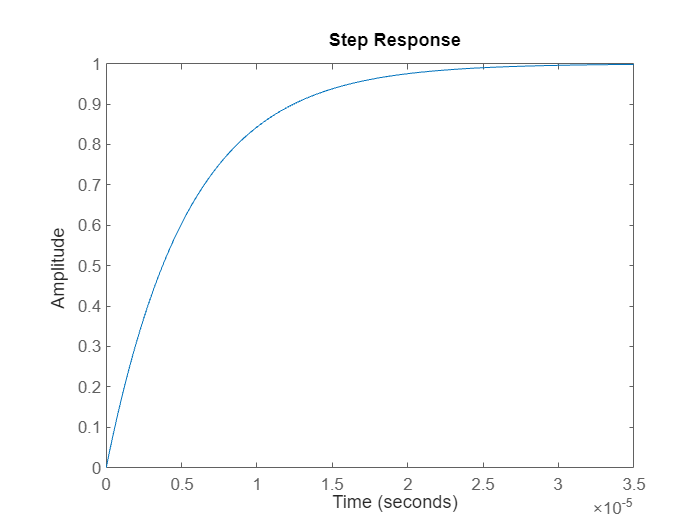

step(T_cc)

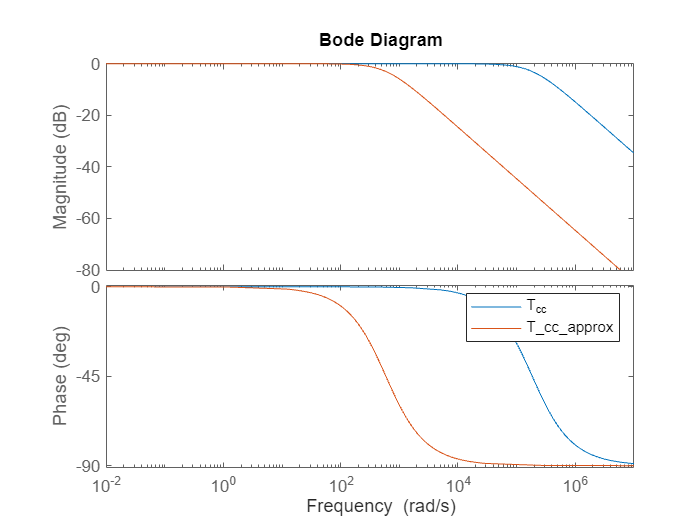

bode(T_cc,1/(ti*s+1))
legend('T_cc', 'T_cc_approx')

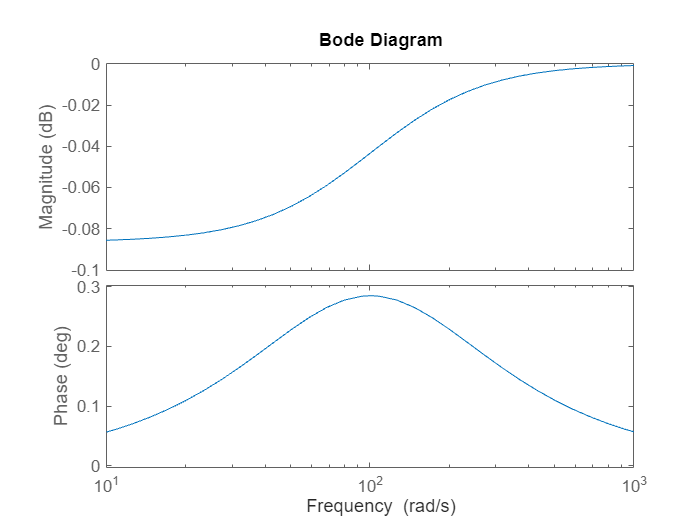

bode(((0.01*s+1)/0.01)/(1+(0.01*s+1)/0.01)) 



% G_plant = 1/(s*l_f/omega_nom+r_f)
% G_grid_plant = 1/(s*x_sys/omega_nom+r_grid)
% dq tf 
i_DQ_plant = [s*l_f/omega_nom+r_f -l_f;
              l_f s*l_f/omega_nom+r_f]

i_DQ_plant =
 
  From input 1 to output...
       0.1056 s + 1.658
   1:  ----------------
            314.2
 
   2:  0.1056
 
  From input 2 to output...
   1:  -0.1056
 
       0.1056 s + 1.658
   2:  ----------------
            314.2
 
Continuous-time transfer function.
Model Properties


i_dq_ctrl = eye(2,2)*G_cc

i_dq_ctrl =
 
  From input 1 to output...
       62.29 s + 3.115
   1:  ---------------
              s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       62.29 s + 3.115
   2:  ---------------
              s
 
Continuous-time transfer function.
Model Properties


 i_dq_ff = [0 -l_f;
            l_f 0]

i_dq_ff =          0   -0.1056
    0.1056         0


i_DQ_grid = [s*x_sys/omega_nom+r_grid -x_sys;
              x_sys  s*x_sys/omega_nom+r_grid]

i_DQ_grid =
 
  From input 1 to output...
       0.8768 s + 19.87
   1:  ----------------
            314.2
 
   2:  0.8768
 
  From input 2 to output...
   1:  -0.8768
 
       0.8768 s + 19.87
   2:  ----------------
            314.2
 
Continuous-time transfer function.
Model Properties


## voltage control



z = 20

z = 20

asind((1-ti*z)/(1+ti*z)) % phase margin

ans = 69.1356

omega_c_vc = sqrt(z/ti)

omega_c_vc = 108.6278

k_vc = (c_f/omega_nom)*omega_c_vc

k_vc = 0.0262

G_vc = k_vc*(s+z)/s

G_vc =
 
  0.02618 s + 0.5235
  ------------------
          s
 
Continuous-time transfer function.
Model Properties


%open
G_forward_vc = k_vc/(ti*(c_f/omega_nom))*((s+z)/(s+1/ti))*1/s^2

G_forward_vc =
 
  6.409e04 s + 1.282e06
  ---------------------
      s^3 + 590 s^2
 
Continuous-time transfer function.
Model Properties


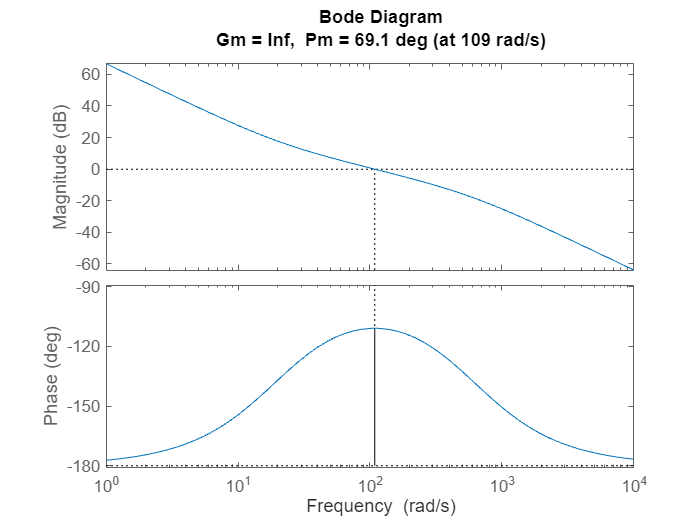

margin(G_forward_vc)

% closed
T_vc = k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2/(1+k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2)

T_vc =
 
          2.338e05 s^4 + 1.426e08 s^3 + 2.759e09 s^2
  -----------------------------------------------------------
  s^6 + 1180 s^5 + 5.819e05 s^4 + 1.426e08 s^3 + 2.759e09 s^2
 
Continuous-time transfer function.
Model Properties


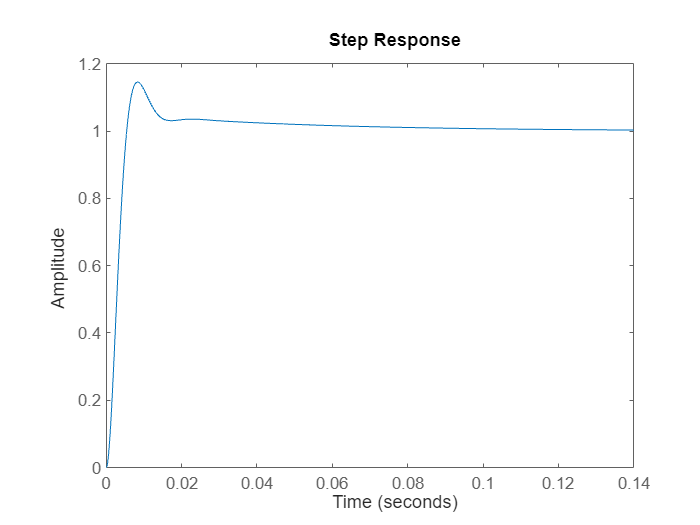

    step(T_vc)

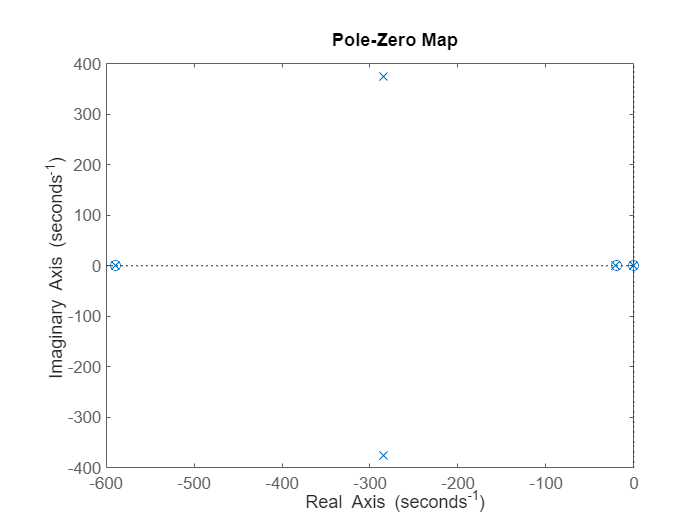

    pzmap(T_vc)


 v_DQ_plant = [s*c_f/omega_nom -c_f;
                c_f s*c_f/omega_nom]

v_DQ_plant =
 
  From input 1 to output...
       0.0757 s
   1:  --------
        314.2
 
   2:  0.0757
 
  From input 2 to output...
   1:  -0.0757
 
       0.0757 s
   2:  --------
        314.2
 
Continuous-time transfer function.
Model Properties


 v_dq_ctrl = eye(2,2)*G_vc

v_dq_ctrl =
 
  From input 1 to output...
       0.02618 s + 0.5235
   1:  ------------------
               s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       0.02618 s + 0.5235
   2:  ------------------
               s
 
Continuous-time transfer function.
Model Properties


 v_dq_ff = [0 -c_f;
            c_f 0]

v_dq_ff =          0   -0.0757
    0.0757         0


## Detailed dc voltage controller

% 
% c_dc =0.00666540000000 % pu  0.47 % aggregated
% % negative 1 is steady state wind power pu
% % cross over frequency is 20 rad/s
%     zigma_dc = 2*l_f*(1)/(3*1^2)
% k0 = 1.5
% G_dc_pre =-k0*2/c_dc*(zigma_dc*s+1)/(s^2*(0.01*s+1)) 
% margin(G_dc_pre)
% step(G_dc_pre/(1+G_dc_pre))
% 
% n0 = 1/(10^(-13/20));
% 
% a = 50; 
% asind((a-1)/(a+1)) % phase margin
% p = sqrt(a)*23;
% N = -n0*(s+p/a)/(s+p)
% bode(N,N*G_dc_pre)
% margin(N*G_dc_pre)
% step(G_dc_pre*N/(1+G_dc_pre*N))
% 
% G_dc = N*k0/s 
% G_dc_num = get(G_dc,'Numerator')
% G_dc_denom = get(G_dc,'Denominator')
% T_dc = -2/c_f*(zigma_dc*s+1)/s
% T_dc_num = get(T_dc,'Numerator')
% T_dc_denom = get(T_dc,'Denominator')

##  dc voltage controller TV

% 
% C_dc_TV = 0.3 % F
% V_dc
% % negative 1 is steady state wind power pu
% % cross over frequency is 20 rad/s
% 
% G_dc_pre =1/(C_dc*s*V_dc) 
% margin(G_dc_pre)
% % step(G_dc_pre/(1+G_dc_pre))
% 
% kp_dc = 0.78;
% ki_dc = 0.85;
% margin(G_dc_pre*G_dc)
% G_dc = 1*(kp_dc + ki_dc/s)
% 
% 
% % a = 50; 
% % asind((a-1)/(a+1)) % phase margin
% % p = sqrt(a)*23;
% % N = -n0*(s+p/a)/(s+p)
% % bode(N,N*G_dc_pre)
% % margin(N*G_dc_pre)
% % step(G_dc_pre*N/(1+G_dc_pre*N))
% step(G_dc_pre*G_dc/(1+G_dc_pre*G_dc)*K_TP)
% G_dc_num = get(G_dc,'Numerator')
% G_dc_denom = get(G_dc,'Denominator')
% T_dc = G_dc_pre
% T_dc_num = get(T_dc,'Numerator')
% T_dc_denom = get(T_dc,'Denominator')

## simplified dc controller

c_dc = 0.47; % pu  aggregated
% cross over frequency is 20 rad/s
dc_plant = -1/(c_dc/omega_nom)*1/s

dc_plant =
 
  -668.4
  ------
    s
 
Continuous-time transfer function.
Model Properties


kp_dc = 0.07;
ki_dc = 0.2

ki_dc = 0.2000

G_dc = -1*(kp_dc + ki_dc/s)

G_dc =
 
  -0.07 s - 0.2
  -------------
        s
 
Continuous-time transfer function.
Model Properties


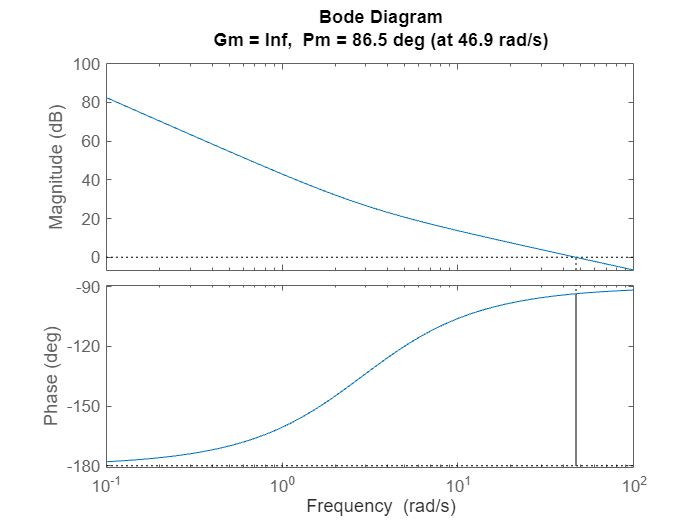


margin(G_dc*dc_plant)

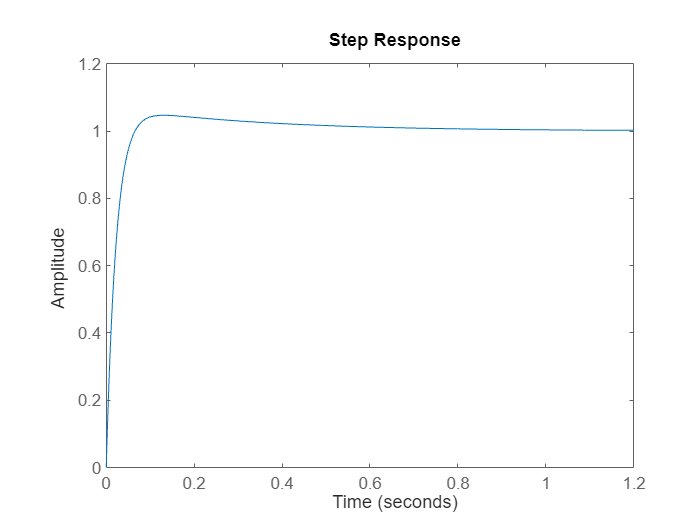

step(G_dc*dc_plant/(1+G_dc*dc_plant))


G_dc_num = get(G_dc,'Numerator')

G_dc_num = 1×1 cell array
    {[-0.0700 -0.2000]}


G_dc_denom = get(G_dc,'Denominator')

G_dc_denom = 1×1 cell array
    {[1 0]}


T_dc = dc_plant

T_dc =
 
  -668.4
  ------
    s
 
Continuous-time transfer function.
Model Properties


T_dc_num = get(T_dc,'Numerator')

T_dc_num = 1×1 cell array
    {[0 -668.4240]}


T_dc_denom = get(T_dc,'Denominator')

T_dc_denom = 1×1 cell array
    {[1 0]}


## Linearized mppt

omega_WTR_0*omega_WTR_n

ans = 0.6399

mppt_gain = 3/2*rho*pi*R_WTR^5*C_p_opt/lambda_opt^3*(omega_WTR_0*omega_WTR_n)^2

mppt_gain = 3.7182e+07

% torsional vibration paper
% v_w_TV = 10
% lambda_opt_TV = 7
% c_p_opt_TV = 0.44
% R_WTR_TV = 63
% omega_WTR_0_TV = v_w_TV*lambda_opt_TV/R_WTR_TV
% omega_WTR_0_TV/1.27

% 0.5*rho*pi*R_WTR_TV^2*c_p_opt_TV*v_w_TV^3
% 0.5*rho*pi*R_WTR_TV^2*c_p_opt_TV*(omega_WTR_0_TV*R_WTR_TV/lambda_opt_TV)^3

15*pi/180

ans = 0.2618

## Linearized two mass model

lambda_op = omega_WTR_0*R_WTR/(v_w_0*v_w_n)

lambda_op = 11.1156

k_tur=-0.04206446159

k_tur = -0.0421

A_m = 1/(2*H_WTR*s)

A_m =
 
    1
  -----
  4.2 s
 
Continuous-time transfer function.
Model Properties


A_g = 1/(2*H_gen*s)

A_g =
 
    1
  -----
  1.8 s
 
Continuous-time transfer function.
Model Properties


A_s = c_drt+k_drt/s

A_s =
 
  s + 280
  -------
     s
 
Continuous-time transfer function.
Model Properties



M_gr = A_s*((A_m*A_s)/(1+A_m*A_s-A_m*k_tur)-1)

M_gr =
 
  -74.09 s^6 - 2.075e04 s^5 - 207.8 s^4
  -------------------------------------
    74.09 s^6 + 18.38 s^5 + 4939 s^4
 
Continuous-time transfer function.
Model Properties


M_gr_num = get(M_gr,'Numerator')

M_gr_num = 1×1 cell array
    {[-74.0880 -2.0745e+04 -207.7648 0 0 0 0]}


M_gr_denom = get(M_gr,'Denominator')

M_gr_denom = 1×1 cell array
    {[74.0880 18.3820 4.9392e+03 0 0 0 0]}



K_Tomega = -P_aero_0/omega_WTR_0^2

K_Tomega = -0.9185

K_TP = 1/omega_WTR_0

K_TP = 1.2373

% Transfer functions

v_dq = [G_vsm; 0; 0]

v_dq =
 
  From input to output...
         314.2
   1:  ----------
       5 s + 2000
 
   2:  0
 
   3:  0
 
Continuous-time transfer function.
Model Properties


v_DQ_t = T_vdq_DQ*v_dq

v_DQ_t =
 
  From input to output...
         -25.72
   1:  ----------
       5 s + 2000
 
         -350.5
   2:  ----------
       5 s + 2000
 
Continuous-time transfer function.
Model Properties


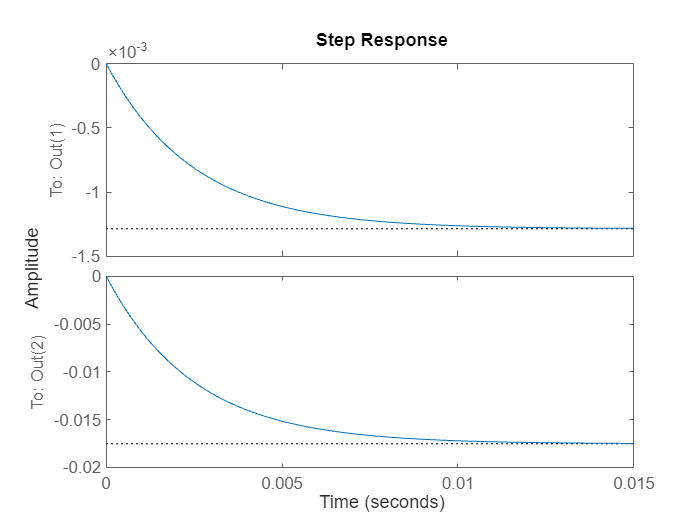

step(v_DQ_t*0.1)

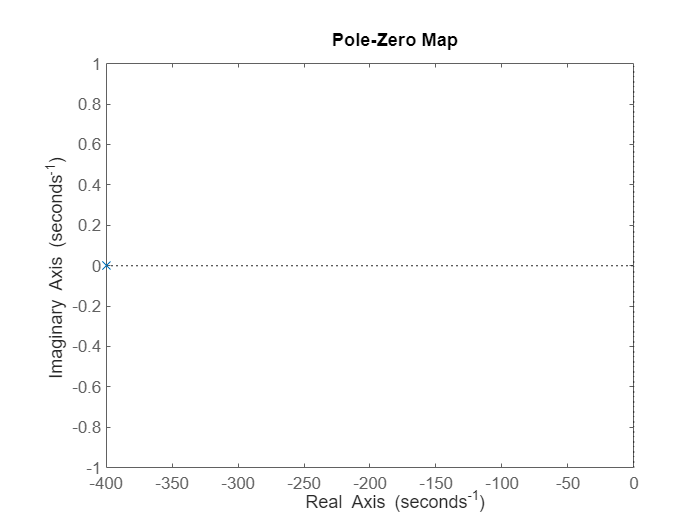

Ggrid = i_DQ_grid;
Gvplant = v_DQ_plant;
Giplant = i_DQ_plant;
pzmap(G_vsm)

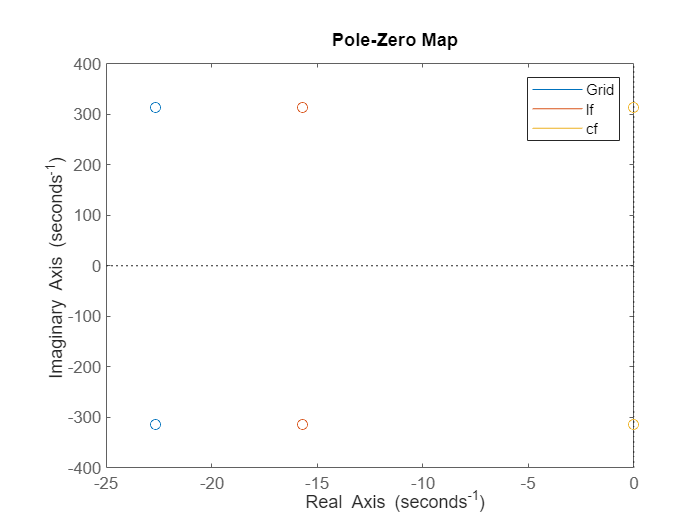

pzmap(Ggrid,Giplant,Gvplant)
legend Grid lf cf


% From v_DQ_t to v_DQ_vsc and i_DQ_vsc when v_Grid = 0


i_DQ_vsc = Giplant^(-1)*v_DQ_t%(-Ggrid*Gvplant + eye(2,2))/(-Ggrid*Gvplant + Ggrid + Giplant)*v_DQ_t % 

i_DQ_vsc =
 
  From input to output...
                   -3.826e05 s^4 - 1.81e09 s^3 - 7.521e11 s^2 - 1.985e14 s - 6.508e16
   1:  ------------------------------------------------------------------------------------------
       25 s^6 + 2.157e04 s^5 + 1.023e07 s^4 + 4.384e09 s^3 + 1.165e12 s^2 + 2.207e14 s + 3.916e16
 
                  -5.215e06 s^4 - 2.212e09 s^3 - 5.651e11 s^2 - 2.021e14 s + 1.515e15
   2:  ------------------------------------------------------------------------------------------
       25 s^6 + 2.157e04 s^5 + 1.023e07 s^4 + 4.384e09 s^3 + 1.165e12 s^2 + 2.207e14 s + 3.916e16
 
Continuous-time transfer function.


v_DQ_vsc =  Ggrid*i_DQ_vsc%Ggrid/(eye(2,2)+Ggrid*Gvplant)*i_DQ_vsc%Ggrid*(-Ggrid*Gvplant + eye(2,2))/((-Ggrid*Gvplant + Ggrid + Giplant)*(Ggrid*Gvplant + eye(2,2)))*v_DQ_t %

v_DQ_vsc =
 
  From input to output...
              -8.387e06 s^11 - 1.118e10 s^10 - 8.986e12 s^9 - 5.776e15 s^8 - 2.816e18 s^7 - 1.134e21 s^6 - 3.859e23 s^5 - 1.049e26 s^4 - 2.444e28 s^3 - 4.474e30 s^2 - 5.861e32 s - 6.698e34
   1:  ---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
       1.963e05 s^12 + 3.388e08 s^11 + 3.068e11 s^10 + 2.075e14 s^9 + 1.106e17 s^8 + 4.743e19 s^7 + 1.713e22 s^6 + 5.157e24 s^5 + 1.286e27 s^4 + 2.693e29 s^3 + 4.395e31 s^2 + 5.429e33 s + 4.817e35
 
                -1.143e08 s^11 - 1.523e11 s^10 - 1.191e14 s^9 - 7.43e16 s^8 - 3.533e19 s^7 - 1.379e22 s^6 - 4.569e24 s^5 - 1.208e27 s^4 - 2.732e29 s^3 - 4.9e31 s^2 - 6.196e33 s - 7.008e35
   2:  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

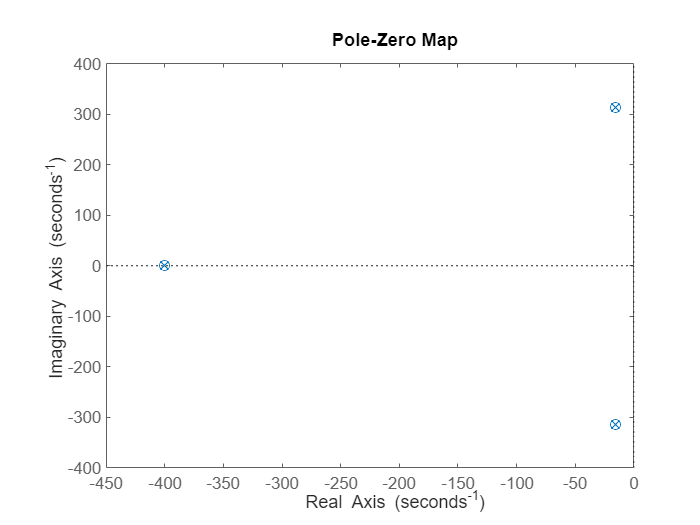



pzmap(i_DQ_vsc)

pzmap(v_DQ_vsc)


% Forward gain from Pref to Pvsc
G_Pref_Pvsc = P_meas*[i_DQ_vsc; v_DQ_vsc]

G_Pref_Pvsc =
 
          -3.61e15 s^35 - 2.022e19 s^34 - 5.77e22 s^33 - 1.118e26 s^32 - 1.653e29 s^31 - 1.986e32 s^30 - 2.018e35 s^29 - 1.779e38 s^28 - 1.387e41 s^27 - 9.684e43 s^26 - 6.123e46 s^25 - 3.532e49 s^24 - 1.871e52 s^23 - 9.142e54 s^22 - 4.135e57 s^21 - 1.737e60 s^20 - 6.79e62 s^19 - 2.473e65 s^18 - 8.404e67 s^17 - 2.665e70 s^16 - 7.884e72 s^15 - 2.175e75 s^14 - 5.587e77 s^13 - 1.334e80 s^12 - 2.955e82 s^11 - 6.047e84 s^10 - 1.138e87 s^9 - 1.96e89 s^8 - 3.062e91 s^7 - 4.299e93 s^6 - 5.345e95 s^5 - 5.771e97 s^4 - 5.251e99 s^3 - 3.831e101 s^2 - 2.042e103 s - 6.218e104
  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------


% closed loop from Pref to Pvsc
T_Pref_Pvsc = (G_Pref_Pvsc/(1+G_Pref_Pvsc))

T_Pref_Pvsc =
 
          -8.699e28 s^71 - 9.375e32 s^70 - 5.098e36 s^69 - 1.866e40 s^68 - 5.175e43 s^67 - 1.16e47 s^66 - 2.191e50 s^65 - 3.581e53 s^64 - 5.173e56 s^63 - 6.706e59 s^62 - 7.892e62 s^61 - 8.515e65 s^60 - 8.487e68 s^59 - 7.865e71 s^58 - 6.812e74 s^57 - 5.54e77 s^56 - 4.247e80 s^55 - 3.078e83 s^54 - 2.116e86 s^53 - 1.383e89 s^52 - 8.614e91 s^51 - 5.121e94 s^50 - 2.912e97 s^49 - 1.585e100 s^48 - 8.279e102 s^47 - 4.15e105 s^46 - 2e108 s^45 - 9.268e110 s^44 - 4.135e113 s^43 - 1.777e116 s^42 - 7.365e118 s^41 - 2.943e121 s^40 - 1.135e124 s^39 - 4.224e126 s^38 - 1.518e129 s^37 - 5.266e131 s^36 - 1.765e134 s^35 - 5.713e136 s^34 - 1.786e139 s^33 - 5.396e141 s^32 - 1.574e144 s^31 - 4.433e146 s^30 - 1.205e149 s^29 - 3.162e151 s^28 - 8.004e153 s^27 - 1.953e156 s^26 - 4.594e158 s^25 - 1.04e161 s^24 - 2.267e163 s^23 - 4.749e165 s^22 - 9.554e167 s^21 - 1.844e170 s^20 - 3.41e172 s^19 - 6.031e174 s^18 - 1.019e177 s^17 - 1.639e179 s^16 - 2.509e181 s^15 - 3.642e183 s^14 - 4.997e185 s^13 - 6.

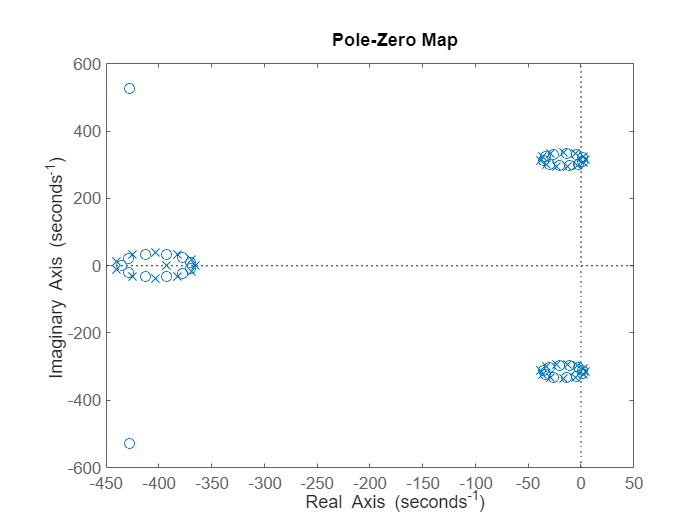


pzmap(G_Pref_Pvsc)

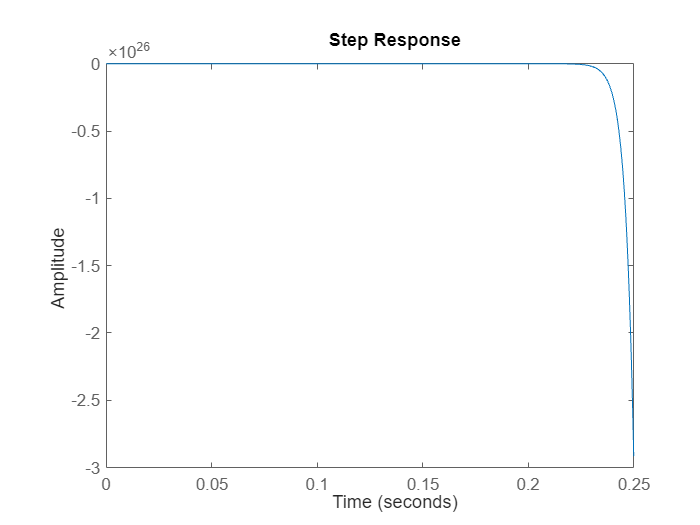

step(T_Pref_Pvsc*0.1)

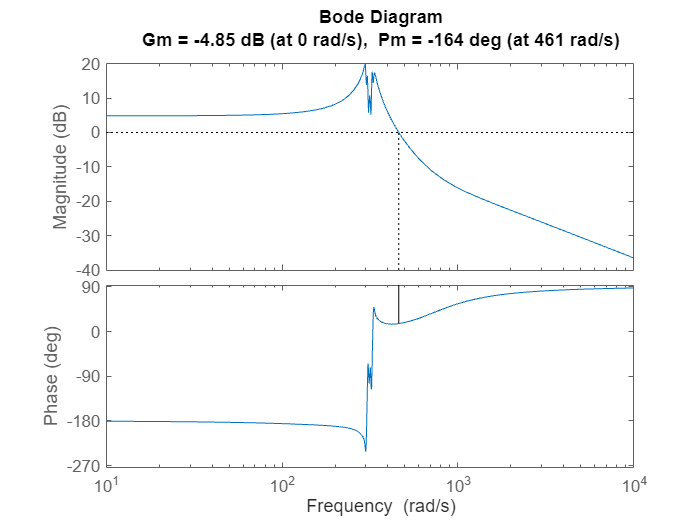

margin(G_Pref_Pvsc)


G_Pref_Pvsc_num = get(G_Pref_Pvsc,'Numerator');
G_Pref_Pvsc_demom = get(G_Pref_Pvsc,'Denominator');
ss_Pref_Pvsc = tf2ss(G_Pref_Pvsc_num{1},G_Pref_Pvsc_demom{1});

sysFeedback = feedback(G_Pref_Pvsc,1)

sysFeedback =
 
              -2.988e13 s^50 - 1.325e17 s^49 - 7.024e20 s^48 - 2.087e24 s^47 - 6.284e27 s^46 - 1.409e31 s^45 - 3.027e34 s^44 - 5.407e37 s^43 - 9.01e40 s^42 - 1.318e44 s^41 - 1.778e47 s^40 - 2.168e50 s^39 - 2.429e53 s^38 - 2.496e56 s^37 - 2.362e59 s^36 - 2.066e62 s^35 - 1.671e65 s^34 - 1.255e68 s^33 - 8.755e70 s^32 - 5.689e73 s^31 - 3.447e76 s^30 - 1.951e79 s^29 - 1.033e82 s^28 - 5.128e84 s^27 - 2.387e87 s^26 - 1.043e90 s^25 - 4.281e92 s^24 - 1.652e95 s^23 - 5.994e97 s^22 - 2.045e100 s^21 - 6.561e102 s^20 - 1.978e105 s^19 - 5.597e107 s^18 - 1.486e110 s^17 - 3.693e112 s^16 - 8.579e114 s^15 - 1.858e117 s^14 - 3.74e119 s^13 - 6.971e121 s^12 - 1.197e124 s^11 - 1.883e126 s^10 - 2.692e128 s^9 - 3.464e130 s^8 - 3.964e132 s^7 - 3.965e134 s^6 - 3.39e136 s^5 - 2.397e138 s^4 - 1.338e140 s^3 - 5.469e141 s^2 - 1.443e143 s - 1.826e144
  ------------------------------------------------------------------------------------------------------------------------------------------------------

poles_PrefPvsc = pole(sysFeedback)

poles_PrefPvsc = 1.0e+03 *

  -0.0412 + 1.5867i
  -0.0412 - 1.5867i
  -0.0112 + 1.5336i
  -0.0112 - 1.5336i
  -0.0115 + 1.5336i
  -0.0115 - 1.5336i
  -0.0113 + 1.5334i
  -0.0113 - 1.5334i
  -0.0114 + 0.9053i
  -0.0114 - 0.9053i
